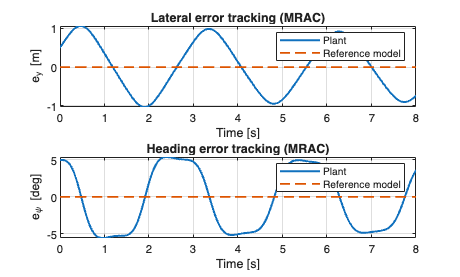

%% Ackermann Steering – Model Reference Adaptive Control (MRAC)
% Adaptive state-feedback controller for the same dynamic bicycle model
% States: [vy; r; ey; eps]
% Control: steering angle delta = -theta(t)^T * x

clear; clc; close all;

%% 1. Nominal vehicle parameters (used for model + design)
m_nom   = 1500;      % mass [kg]
Iz_nom  = 2250;      % yaw inertia [kg m^2]
lf      = 1.2;       % CG to front axle [m]
lr      = 1.6;       % CG to rear axle [m]
Cf_nom  = 80e3;      % front cornering stiffness [N/rad]
Cr_nom  = 80e3;      % rear cornering stiffness [N/rad]
Ux0     = 15;        % nominal forward speed [m/s]

[A0, B0] = lateral_dynamics_matrix(m_nom, Iz_nom, lf, lr, Cf_nom, Cr_nom, Ux0);

%% 2. Design a baseline LQR (to define reference model Am)
Q_lqr = diag([10, 1, 50, 10]);  % same as before or tune as you like
R_lqr = 1;
K_des = lqr(A0, B0, Q_lqr, R_lqr);  % 1x4 row vector

% Reference model: desired closed-loop dynamics
Am = A0 - B0 * K_des;   % 4x4
% No external reference input (regulation to x=0): x_mdot = Am * x_m

%% 3. True plant parameters (introduce mismatch)
% Imagine the real car is heavier and tire stiffness is different
m_true  = 1700;          % +200 kg
Iz_true = 2600;          % larger inertia
Cf_true = 0.7 * Cf_nom;  % 30% less front stiffness (bad road/tyres)
Cr_true = 1.2 * Cr_nom;  % 20% more rear stiffness
Ux_true = 20;            % actual speed is higher than design

[A_true, B_true] = lateral_dynamics_matrix(m_true, Iz_true, lf, lr, Cf_true, Cr_true, Ux_true);

%% 4. MRAC design: P (Lyapunov) and adaptation gain Gamma
Qm = eye(4);                    % choose for Lyapunov equation
P  = lyap(Am', Qm);             % solve Am^T P + P Am = -Qm

Gamma = diag([2, 2, 3, 3]); % adaptation gains (tune)
Ba    = B0;                     % nominal input matrix used in adaptation

%% 5. Simulate combined system: [x; x_m; theta]
% State vector: X = [x(4); x_m(4); theta(4)]
x0   = [0; 0; 0.5; 5*pi/180];   % initial plant state (0.5 m lateral error, 5 deg heading error)
xm0  = zeros(4,1);              % reference model starts at zero
theta0 = zeros(4,1);            % start with zero feedback gains (controller learns from scratch)

X0 = [x0; xm0; theta0];

tspan = [0 8];                  % simulate 8 seconds

% ODE for MRAC closed-loop
odefun = @(t, X) mrac_dynamics(t, X, A_true, B_true, Am, Ba, P, Gamma);

[t, X] = ode45(odefun, tspan, X0);

% Extract variables
x_hist   = X(:, 1:4);       % plant
xm_hist  = X(:, 5:8);       % reference model
theta_hist = X(:, 9:12);    % 4 adaptive gains

vy   = x_hist(:,1);
r    = x_hist(:,2);
ey   = x_hist(:,3);
epsi = x_hist(:,4);

ey_m   = xm_hist(:,3);
epsi_m = xm_hist(:,4);

% Recover control input u(t) = -theta^T x
u_hist = -sum(theta_hist .* x_hist, 2);   % elementwise multiply and sum across states

%% 6. Plot tracking performance
figure;
subplot(2,1,1);
plot(t, ey, 'LineWidth', 1.5); hold on;
plot(t, ey_m, '--', 'LineWidth', 1.2);
grid on;
xlabel('Time [s]');
ylabel('e_y [m]');
legend('Plant', 'Reference model');
title('Lateral error tracking (MRAC)');

subplot(2,1,2);
plot(t, epsi * 180/pi, 'LineWidth', 1.5); hold on;
plot(t, epsi_m * 180/pi, '--', 'LineWidth', 1.2);
grid on;
xlabel('Time [s]');
ylabel('e_\psi [deg]');
legend('Plant', 'Reference model');
title('Heading error tracking (MRAC)');

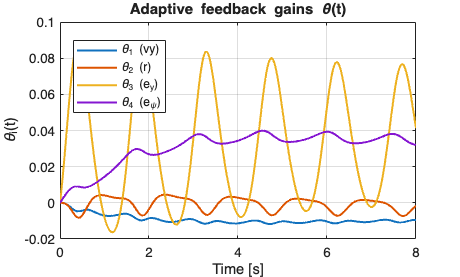


%% 7. Plot adaptive gains
figure;
plot(t, theta_hist, 'LineWidth', 1.5);
grid on;
xlabel('Time [s]');
ylabel('\theta_i(t)');
title('Adaptive feedback gains \theta(t)');
legend('\theta_1 (vy)', '\theta_2 (r)', '\theta_3 (e_y)', '\theta_4 (e_\psi)', 'Location', 'best');

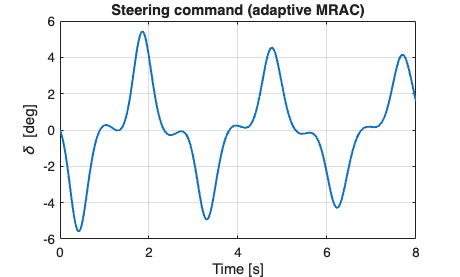


%% 8. Plot steering command
figure;
plot(t, u_hist * 180/pi, 'LineWidth', 1.5);
grid on;
xlabel('Time [s]');
ylabel('\delta [deg]');
title('Steering command (adaptive MRAC)');



%% -------- Local functions --------

function dX = mrac_dynamics(~, X, A_true, B_true, Am, Ba, P, Gamma)
    % Unpack combined state
    x   = X(1:4);        % plant state
    xm  = X(5:8);        % reference model state
    th  = X(9:12);       % adaptive parameter vector (theta)

    % Control law: u = -theta^T x
    u = -th' * x;

    % Plant and model dynamics
    xdot  = A_true * x + B_true * u;
    xmdot = Am * xm;

    % Tracking error
    e = x - xm;

    % Adaptive law: theta_dot = -Gamma * x * (e^T P Ba)
    sigma    = e' * P * Ba;  % scalar
    sigma_th = 0.5;
    th_dot   = Gamma * x * sigma - sigma_th*th;

    % Pack derivative
    dX = [xdot;
          xmdot;
          th_dot];
end

function [A, B] = lateral_dynamics_matrix(m, Iz, lf, lr, Cf, Cr, Ux)
    % Build linear lateral dynamics A,B for dynamic bicycle model
    % States: [vy; r; ey; eps]
    A = zeros(4,4);
    B = zeros(4,1);

    A(1,1) = (-2*Cf/Ux - 2*Cr/Ux)/m;
    A(1,2) = (-2*Cf*lf/Ux + 2*Cr*lr/Ux - m*Ux)/m;
    A(2,1) = (-2*Cf*lf/Ux + 2*Cr*lr/Ux)/Iz;
    A(2,2) = (-2*Cf*lf^2/Ux - 2*Cr*lr^2/Ux)/Iz;

    A(3,1) = 1;
    A(3,4) = Ux;
    A(4,2) = 1;

    B(1,1) = 2*Cf/m;
    B(2,1) = 2*Cf*lf/Iz;
end
